
% Section 1: Load composition data
compositionData = readtable('composition_includingtestdata.csv');


% Section 2: Load IR spectra data
spectraData = readtable('all_spectra_includingtestdata.csv');


% Extract 'Sample' column for common identifier
commonIdentifier = compositionData.Properties.VariableNames;


rng(123);

% Extract predictors (X) and response variable (y)
X = table2array(spectraData(:, 2:end));


% Display the first few rows of predictors (X) and response variable (y)
disp('Predictors (X) (First Few Rows):');

Predictors (X) (First Few Rows):


disp(X(1:5, :));

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1930    0.1770    0.1740    0.1460    0.2220    0.1470    0.2010    0.2440    0.2320    0.1850    0.2190    0.2070    0.1380    0.1730    0.1090    0.0509    0.0434    0.0918    0.1230    0.1980    0.1510    0.1700    0.1390    0.1630    0.1910    0.2460    0.2440    0.1490    0.1920    0.2720    0.0616    0.0833    0.1330    0.0437    0.0741    0.0824    0.1020    0.0370    0.0802    0.1550    0.0749    0.1370    0.1150    0.1430    0.1870    0.044

% Extract response variable (y) from 'composition.csv'
y = table2array(compositionData(1:end, 2:end));

disp('Response Variable (y) (First Few Rows):');

Response Variable (y) (First Few Rows):


disp(y)

         0         0         0  100.0000  100.0000  100.0000         0         0         0   24.6300   24.6300   24.6300   48.7800   48.7800   48.7800   23.1500   23.1500   23.1500   24.6300   24.6300   24.6300   74.2600   74.2600   74.2600         0         0         0   24.8800   24.8800   24.8800   33.1700   33.1700   33.1700         0         0         0   74.2600   74.2600   74.2600   19.9000   19.9000   19.9000   18.9600   18.9600   18.9600   24.2700   24.2700   24.2700   19.9000   19.9000   19.9000   28.3000       NaN       NaN
         0         0         0         0         0         0  100.0000  100.0000  100.0000   26.1100   26.1100   26.1100   26.8300   26.8300   26.8300   53.7000   53.7000   53.7000         0         0         0         0         0         0   75.0000   75.0000   75.0000   75.1200   75.1200   75.1200   33.6700   33.6700   33.6700   25.0000   25.0000   25.0000   25.7400   25.7400   25.7400   70.1500   70.1500   70.1500   12.3200   12.3200   12.3200   59.710

y_cellulose = table2array(compositionData(1,2:end))

y_cellulose =          0         0         0  100.0000  100.0000  100.0000         0         0         0   24.6300   24.6300   24.6300   48.7800   48.7800   48.7800   23.1500   23.1500   23.1500   24.6300   24.6300   24.6300   74.2600   74.2600   74.2600         0         0         0   24.8800   24.8800   24.8800   33.1700   33.1700   33.1700         0         0         0   74.2600   74.2600   74.2600   19.9000   19.9000   19.9000   18.9600   18.9600   18.9600   24.2700   24.2700   24.2700   19.9000   19.9000


y_hemicellulose = table2array(compositionData(2,2:end))

y_hemicellulose =          0         0         0         0         0         0  100.0000  100.0000  100.0000   26.1100   26.1100   26.1100   26.8300   26.8300   26.8300   53.7000   53.7000   53.7000         0         0         0         0         0         0   75.0000   75.0000   75.0000   75.1200   75.1200   75.1200   33.6700   33.6700   33.6700   25.0000   25.0000   25.0000   25.7400   25.7400   25.7400   70.1500   70.1500   70.1500   12.3200   12.3200   12.3200   59.7100   59.7100   59.7100   44.7800   44.7800


y_lignin = table2array(compositionData(3,2:end))

y_lignin =   100.0000  100.0000  100.0000         0         0         0         0         0         0   49.2600   49.2600   49.2600   24.3900   24.3900   24.3900   23.1500   23.1500   23.1500   75.3700   75.3700   75.3700   25.7400   25.7400   25.7400   25.0000   25.0000   25.0000         0         0         0   33.1600   33.1600   33.1600   75.0000   75.0000   75.0000         0         0         0    9.9500    9.9500    9.9500   68.7200   68.7200   68.7200   16.0200   16.0200   16.0200   35.3200   35.3200


disp(size(X,2))

    54



disp(length(y_cellulose))

    54



X_transposed = X'

X_transposed =          0    0.1930    0.1850    0.1760    0.1680    0.1610    0.1560    0.1540    0.1560    0.1610    0.1690    0.1770    0.1830    0.1860    0.1860    0.1820    0.1770    0.1710    0.1650    0.1610    0.1580    0.1570    0.1570    0.1590    0.1620    0.1640    0.1650    0.1640    0.1620    0.1600    0.1580    0.1570    0.1580    0.1590    0.1600    0.1620    0.1630    0.1630    0.1620    0.1620    0.1620    0.1620    0.1620    0.1610    0.1600    0.1590    0.1580    0.1570    0.1560    0.1560
         0    0.1770    0.1780    0.1790    0.1780    0.1740    0.1700    0.1670    0.1660    0.1690    0.1740    0.1810    0.1860    0.1890    0.1900    0.1880    0.1860    0.1840    0.1820    0.1800    0.1770    0.1740    0.1700    0.1670    0.1630    0.1610    0.1590    0.1590    0.1590    0.1590    0.1600    0.1610    0.1620    0.1640    0.1670    0.1690    0.1710    0.1730    0.1730    0.1720    0.1710    0.1690    0.1660    0.1630    0.1610    0.1600    0.1590    0.1590    

y_cellulose_transposed = y_cellulose'

y_cellulose_transposed =          0
         0
         0
  100.0000
  100.0000
  100.0000
         0
         0
         0
   24.6300


y_hemicellulose_transposed = y_hemicellulose'

y_hemicellulose_transposed =          0
         0
         0
         0
         0
         0
  100.0000
  100.0000
  100.0000
   26.1100


y_lignin_transposed = y_lignin'

y_lignin_transposed =   100.0000
  100.0000
  100.0000
         0
         0
         0
         0
         0
         0
   49.2600


model_cellulose = fitrlinear(X_transposed, y_cellulose_transposed)

model_cellulose =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [7469×1 double]
                 Bias: 28.4716
               Lambda: 0.0192
              Learner: 'svm'


  Properties, Methods


model_hemicellulose = fitrlinear(X_transposed, y_hemicellulose_transposed)

model_hemicellulose =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [7469×1 double]
                 Bias: 42.7683
               Lambda: 0.0192
              Learner: 'svm'


  Properties, Methods


model_lignin = fitrlinear(X_transposed, y_lignin_transposed)

model_lignin =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [7469×1 double]
                 Bias: 27.7318
               Lambda: 0.0192
              Learner: 'svm'


  Properties, Methods


Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       7 | Accept |      6.7917 |     0.45423 |      6.7137 |      6.7527 |       152.24 | leastsquares |
|    2 |       7 | Best   |      6.7137 |     0.50017 |      6.7137 |      6.7527 |       5.3765 |          svm |
|    3 |       3 | Best   |      4.2351 |      1.3255 |      4.2351 |      4.2354 |   5.7934e-05 |          svm |
|    4 |       3 | Accept |      4.4232 |      1.4595 |      4.2351 |      4.2354 |   2.7885e-07 |          svm |
|  

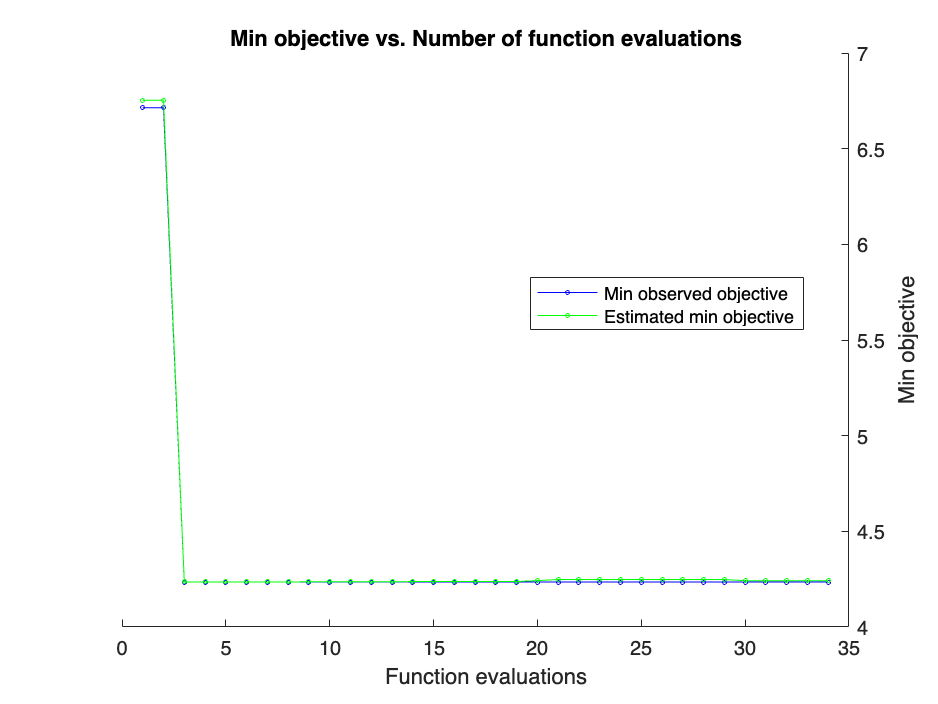

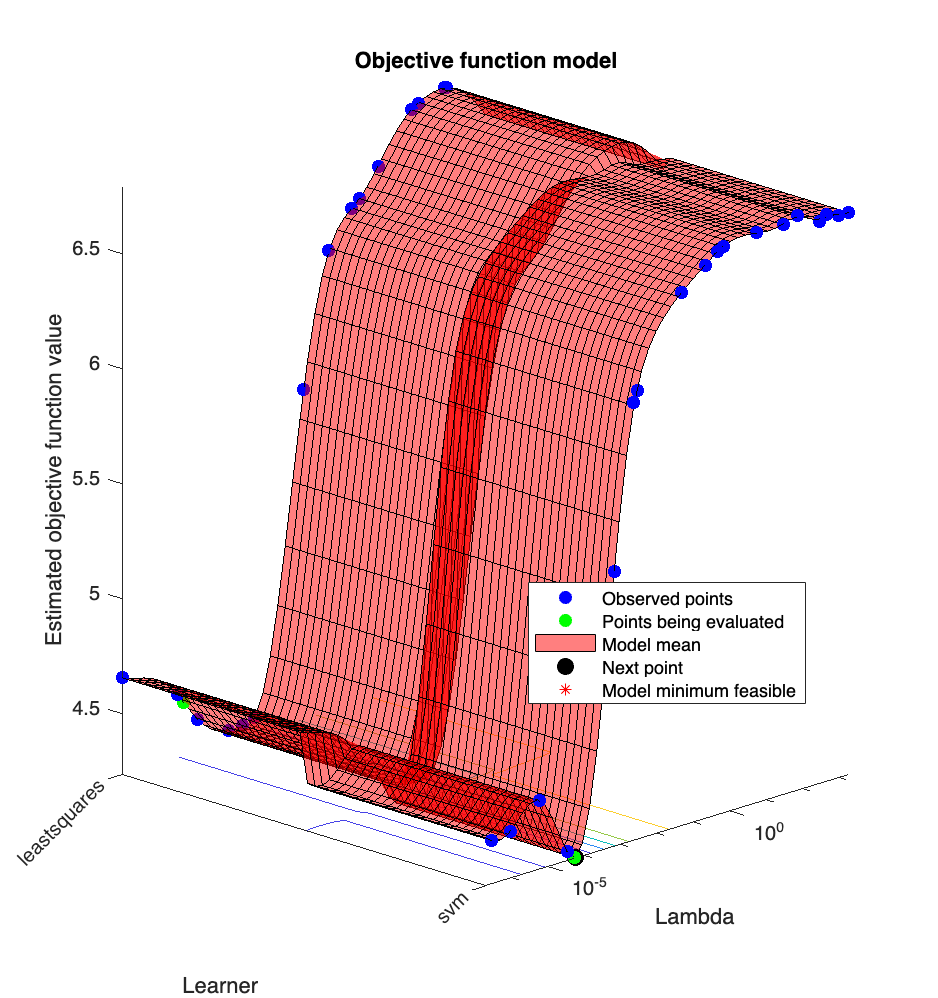

Total objective function evaluation time: 51.2611

Best observed feasible point:
      Lambda      Learner
    __________    _______

    5.7934e-05      svm  

Observed objective function value = 4.2351
Estimated objective function value = 4.2418
Function evaluation time = 1.3255

Best estimated feasible point (according to models):
      Lambda      Learner
    __________    _______

    5.7934e-05      svm  

Estimated objective function value = 4.2418
Estimated function evaluation time = 1.1584





% Define hyperparameter search space
t = templateLinear('Learner', 'leastsquares');


% Specify hyperparameter options for fitrlinear
hyperparameters = struct(...
    'Lambda', 'auto', ...  % Automatically determine the strength of regularization
    'Regularization', 'ridge', ...  % Specify ridge regularization
    'Solver', 'sgd', ...  % Use Stochastic Gradient Descent (you can adjust this based on your data)
    'GradientTolerance', 1e-4, ...  % Tolerance for stopping criterion
    'Learner', 'leastsquares', ...  % Base learner
    'OptimizeLearnRate', true ...  % Optimize the learning rate during training
);

% Specify optimization options
opt = struct(...
    'AcquisitionFunctionName', 'expected-improvement-plus', ...  % Choose the acquisition function
    'UseParallel', true ...  % Use parallel computing if available
);

% Train PLS regression models with hyperparameter tuning
model_cellulose = fitrlinear(X_transposed, y_cellulose, 'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', opt);

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       8 | Best   |      6.9234 |       0.505 |      6.9234 |      6.9234 |       467.46 |          svm |
|    2 |       5 | Accept |      6.6792 |     0.76329 |       4.872 |      4.8722 |       2.3433 | leastsquares |
|    3 |       5 | Accept |      6.5785 |      1.1818 |       4.872 |      4.8722 |        0.016 |          svm |
|    4 |       5 | Accept |      6.9235 |     0.59087 |       4.872 |      4.8722 |       676.63 |          svm |
|  

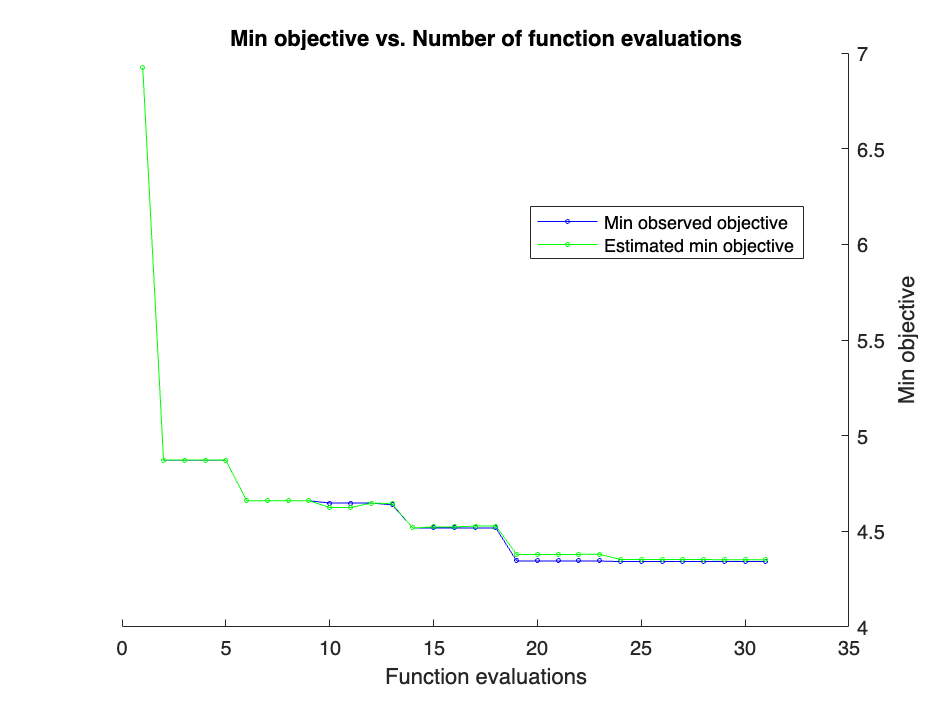

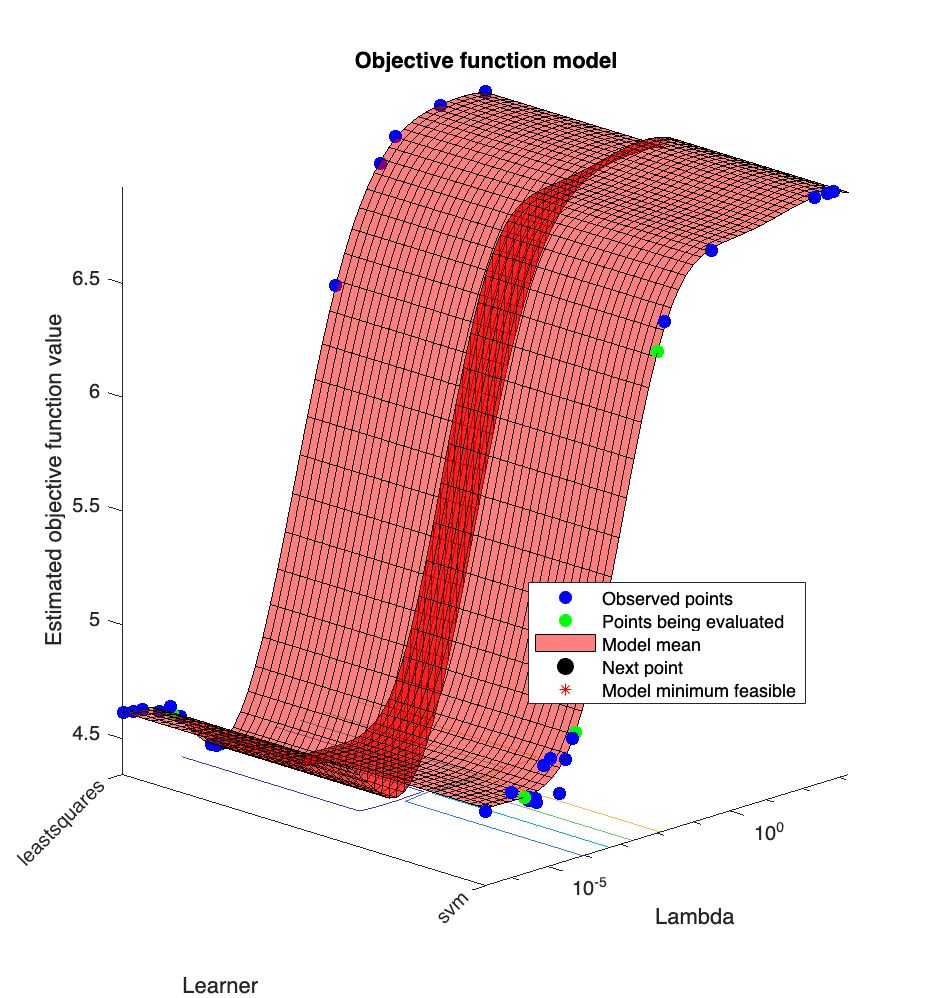


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 31
Total elapsed time: 33.4475 seconds
Total objective function evaluation time: 148.0775

Best observed feasible point:
      Lambda        Learner   
    __________    ____________

    7.2652e-05    leastsquares

Observed objective function value = 4.3418
Estimated objective function value = 4.3512
Function evaluation time = 7.6397

Best estimated feasible point (according to models):
      Lambda        Learner   
    __________    ____________

    7.2652e-05    leastsquares

Estimated objective function value = 4.3512
Estimated function evaluation time = 6.6271



model_hemicellulose = fitrlinear(X_transposed, y_hemicellulose, 'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', opt);

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       8 | Best   |      6.6447 |     0.57901 |      6.6447 |      6.6447 |       7.2922 | leastsquares |
|    2 |       5 | Best   |      4.0924 |      2.3375 |      4.0924 |      4.0925 |   8.8658e-05 |          svm |
|    3 |       5 | Accept |      6.8448 |     0.88882 |      4.0924 |      4.0925 |       6.6308 |          svm |
|    4 |       5 | Accept |      4.5556 |     0.89637 |      4.0924 |      4.0925 |      0.15065 | leastsquares |
|  

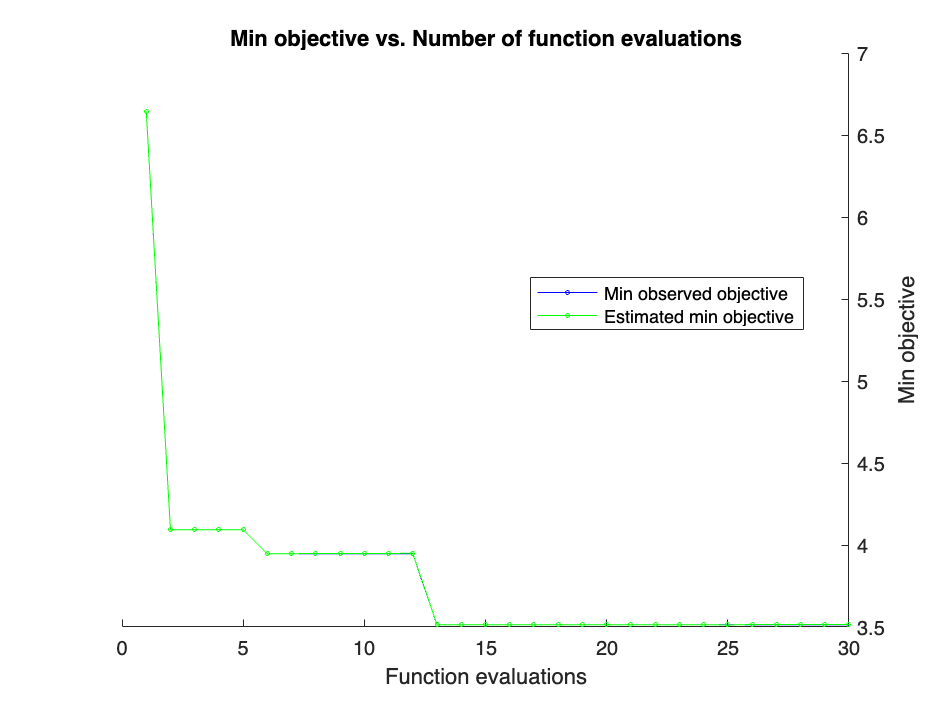

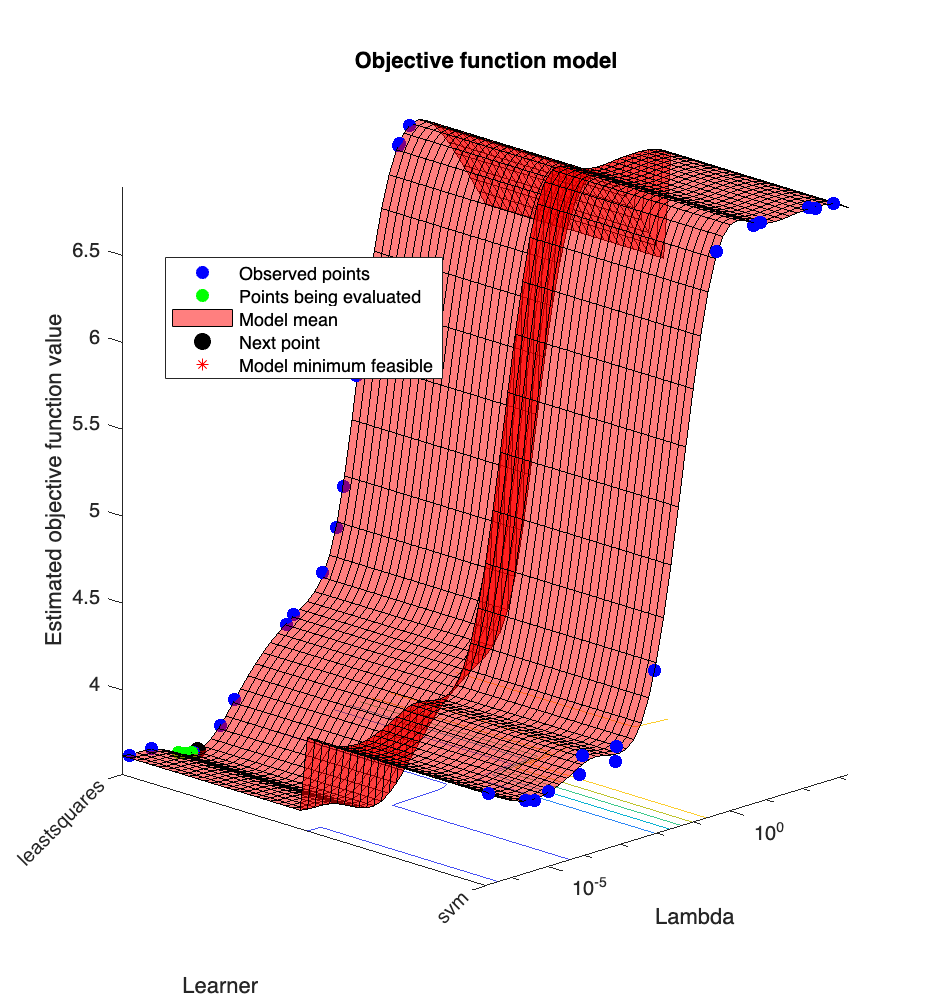

model_lignin = fitrlinear(X_transposed, y_lignin, 'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', opt);


testData = readtable('CS_lots_of_threads-3.CSV');
testSpectra = table2array(testData(:,2));
testSpectra_transposed = testSpectra'

testSpectra_transposed =          0    0.0599    0.0564    0.0507    0.0436    0.0366    0.0312    0.0282    0.0276    0.0290    0.0313    0.0336    0.0350    0.0351    0.0341    0.0321    0.0295    0.0268    0.0243    0.0225    0.0219    0.0228    0.0253    0.0290    0.0334    0.0377    0.0412    0.0436    0.0447    0.0445    0.0434    0.0415    0.0391    0.0363    0.0332    0.0303    0.0280    0.0268    0.0273    0.0296    0.0330    0.0367    0.0398    0.0416    0.0423    0.0422    0.0416    0.0411    0.0408    0.0407




% Make predictions on test data
predicted_cellulose = predict(model_cellulose, testSpectra_transposed)

predicted_cellulose = 27.7766

predicted_hemicellulose = predict(model_hemicellulose, testSpectra_transposed)

predicted_hemicellulose = 51.5199

predicted_lignin = predict(model_lignin, testSpectra_transposed)

predicted_lignin = 10.4752



% Model evaluation
Ypred_cellulose = predict(model_cellulose, X_transposed);
mse_cellulose = mse(y_cellulose, Ypred_cellulose);
rmse_cellulose = sqrt(mse_cellulose);

disp(['Mean Squared Error (Cellulose): ' num2str(mse_cellulose)]);

Mean Squared Error (Cellulose): 1666.4158


disp(['Root Mean Squared Error (Cellulose): ' num2str(rmse_cellulose)]);

Root Mean Squared Error (Cellulose): 40.8218
